# scr20230711_110047_calibrate_SharpTrack.mlx

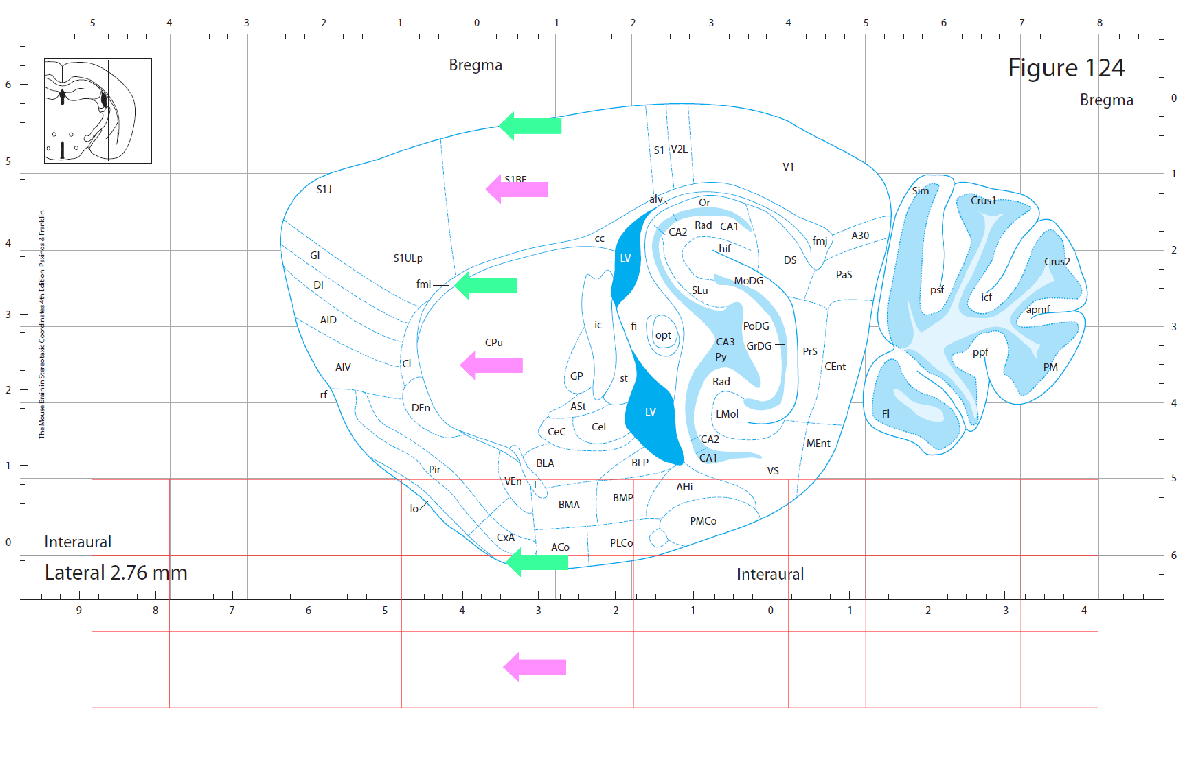


shtr.AP = [-0.11, 0.22, -0.34]

shtr = struct with fields:
    AP: [-0.1100 0.2200 -0.3400]

shtr.DV = [1.18, 3.46, 7.37]

shtr = struct with fields:
    AP: [-0.1100 0.2200 -0.3400]
    DV: [1.1800 3.4600 7.3700]


pafr.AP = [-0.284, 0.297, -0.370]

pafr = struct with fields:
    AP: [-0.2840 0.2970 -0.3700]

pafr.DV = [0.361, 2.429, 6.012]

pafr = struct with fields:
    AP: [-0.2840 0.2970 -0.3700]
    DV: [0.3610 2.4290 6.0120]

figure
ax = axes

ax =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties

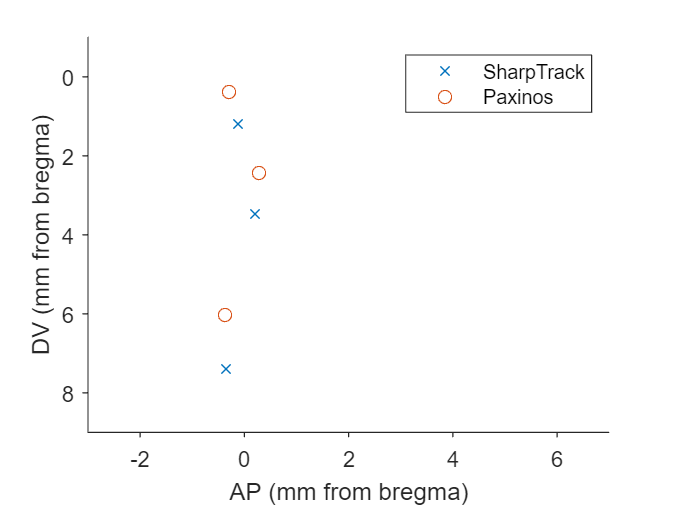

plot(shtr.AP, shtr.DV, 'x', DisplayName='SharpTrack')
hold on
plot(pafr.AP, pafr.DV, 'o', DisplayName='Paxinos')
ax.YDir = 'reverse';
xlim([-3, 7])
ylim([-1. 9])
box off;
tickdir out;
legend(Location='northeast')
xlabel('AP (mm from bregma)')
ylabel('DV (mm from bregma)')

figure;
ax = axes;
plot(shtr.DV, pafr.DV, 'o')
box off;
tickdir out;
xlabel('DV in SharpTrack (mm from bregma)')
ylabel('DV in Paxinos (mm from bregma)')

X = [ones(size(shtr.DV')) , shtr.DV']

X =     1.0000    1.1800
    1.0000    3.4600
    1.0000    7.3700


Y = pafr.DV';
b = X\Y

b =    -0.7222
    0.9133


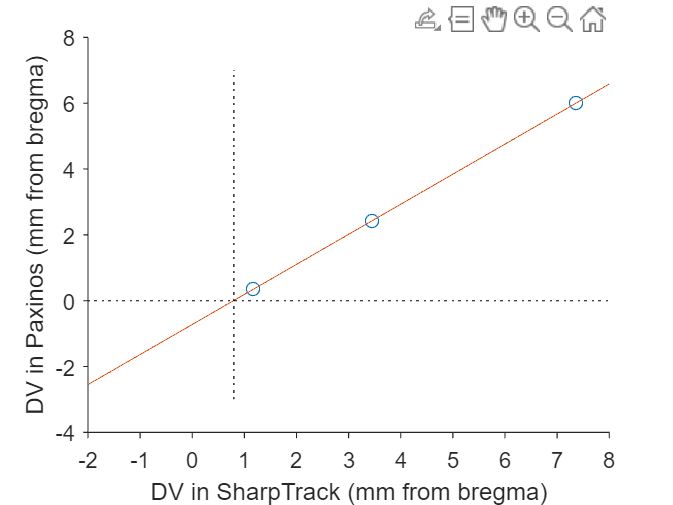


x = -2:0.01:8; % 10 micron
y = b(1) + b(2) * x;

hold on
ax.XTick = -2:8;
plot(x, y);
plot(xlim, [0 0], 'k:')
plot([x(find(y >=0,1,"first")), x(find(y >=0,1,"first"))], ylim, 'k:')

fprintf("At y = 0, i.e. the real bregma, SharpTrack DV value is %.3f mm\n", x(find(y >=0,1,"first")));

At y = 0, i.e. the real bregma, SharpTrack DV value is -0.722 mm


fprintf("SharpTrack depth x can be converted to Paxinos depth by y = %.3f * x %+.3f\n", b(2), b(1));

SharpTrack depth x can be converted to Paxinos depth by y = 0.913 * x -0.722
